### Conceptual Questions

- Correlation is a statistical measure that expresses the extent to which two variables are linearly related (meaning they change together at a constant rate). It’s a common tool for describing simple relationships without making a statement about cause and effect. We can have positive, negative or zero correlation. Positive or negtive, determines that 2 variables move in the same dirrection or not(increase of V1 -> increase/decrease of V2)

- If we want to calculate the correlation of two matrices, a simple solution would be this: We first make the scale of two matrices equal; For example, two matrices(A , B) become n*m . And then :


$$\mathrm{correlation}=\;\sum_{i=0}^n \sum_{j=0}^m A\left(i,j\right)\ldotp B\left(i,j\right)$$


          3. Consider an unknown object OBJ that we want to recognize it, We simply calculate correlation of OBJ with each of pre-defined objects. The type of object that its correlation value with OBJ is more than the other objects, will be considered as the type of unknown object OBJ.

loading training set and opening picture :

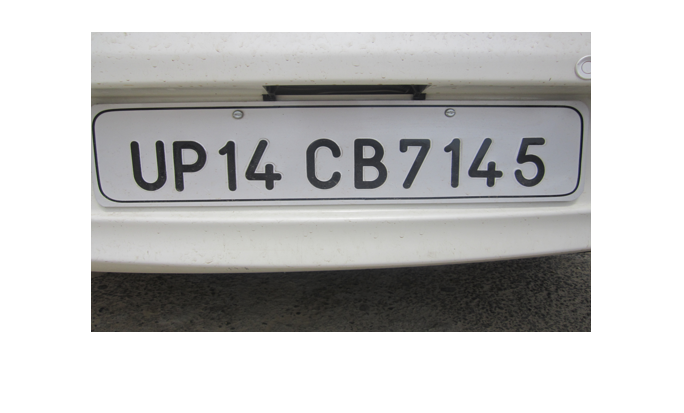

close all
clear
clc
mapDir = 'Map Set';

train_set = loadMaps(mapDir);
plate_pic = openPlate();
imshow(plate_pic)

Four first lines of this section, determines hyper parameters which is necessary for cleaning img or extracting objcet.

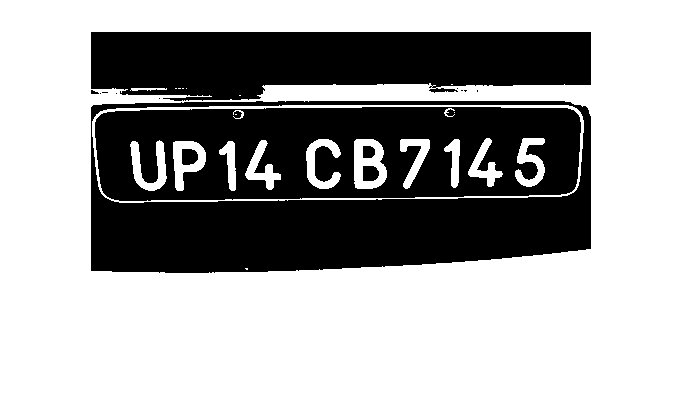

erodingDiskStrucElm_r = 0;
erodingDiskStrucElm_n = 8;
maxPixelsToRemove = 200;
thresholdCorrValue = 0.5;

plate_pic_bw = rgb2Bw(plate_pic);
imshow(plate_pic_bw)

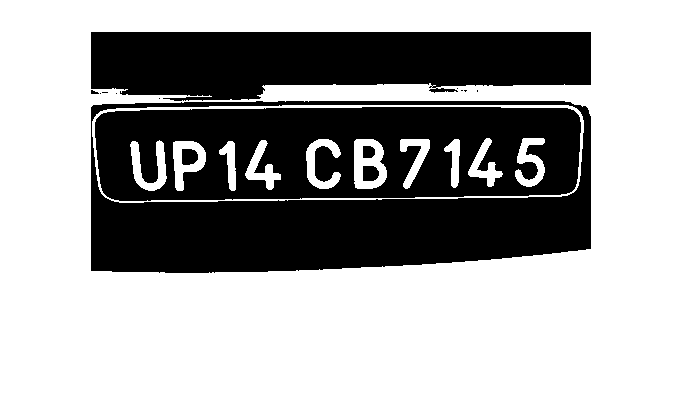

plate_pic_bw_clean = cleanBw(plate_pic_bw, erodingDiskStrucElm_r, erodingDiskStrucElm_n, maxPixelsToRemove);
imshow(plate_pic_bw_clean)

extraction :

extracted = extract(plate_pic_bw_clean, train_set, thresholdCorrValue)

extracted = 'UP14CB7145'

Some Notes :

** In openPlate function, we also resize the selected picture.

** In rgb2Bw fuction, instead of using matab function to make picture gray,we use the formula in CA description.

** In cleanBw function, we fist use edoring method and then we use bwareaopen matlab function to remove small objects.

** mapCorr returns map of object_type : value of 2d correlation of object with map1 arg

** extract function returns list of extracted chars from imgClean argument picture.

function plateArrC = openPlate()
    [file,path] = uigetfile({'*.jpg';'*.bmp';'*.png';'*.tif'}, 'Choose a picture');
    address = [path,file];
    picture = imread(address);
    plateArrC = imresize(picture, [300 500]);
end

function imgBw = rgb2Bw(imgColored)
    %imgBw = rgb2gray(imgColored);
    imgBw = 0.299*imgColored(:,:,1) + 0.587*imgColored(:,:,2) + 0.114*imgColored(:,:,3);
    threshold = graythresh(imgBw);
    imgBw = ~im2bw(imgBw, threshold);
end

function imgClean = cleanBw(imgNoisy, erodingDiskStrucElm_r, erodingDiskStrucElm_n, minPixelsToRemove)
    se = strel('disk', erodingDiskStrucElm_r, erodingDiskStrucElm_n);
    imgClean = imerode(imgNoisy,se);
    imgClean = bwareaopen(imgClean, minPixelsToRemove);
end

function mapSet = loadMaps(mapDir)
    dirContent = dir(mapDir);
    baseFullAddr = dirContent.folder;
    fileNmes = {dirContent(3:end).name};
    train_set = containers.Map;
    for i=1:length(fileNmes)
        train_set(fileNmes{i}) = imread([baseFullAddr, '\', fileNmes{i}]);
    end
    mapSet = train_set;
end

function rho = mapCorr(map1, mapSet)
    corr_results = containers.Map;
    map_names = mapSet.keys();
    map_size_of_set = size(mapSet(map_names{1}));
    map1 = imresize(map1, [map_size_of_set(1) map_size_of_set(2)]);
    for i=1:mapSet.length()
        corr_results(map_names{i}) = corr2(map1, mapSet(map_names{i}));
    end
    rho = corr_results;
end

function extracted = extract(imgClean, mapSet, thresholdCorrValue)
    [L, Ne] = bwlabel(imgClean);
    extracted = [];
    for obj_ind=1:Ne
        [rows, cols] = find(L == obj_ind);
        croped_obj = imgClean(min(rows):max(rows), min(cols):max(cols));
        corr_results = mapCorr(croped_obj, mapSet);
        max_corr_value = max(cell2mat(values(corr_results)));
        obj_type_ind = find(cell2mat(values(corr_results))==max_corr_value, 1);
        types = keys(corr_results);
        %types{obj_type_ind}(1)
        %max_corr_value
        if max_corr_value > thresholdCorrValue
            extracted = [extracted, types{obj_type_ind}(1)];
        end
    end
end
